# Problema de Despacho Econômico para 3 Geradores

## Parâmetros do algoritmo

clear,clc
tic
n = 100; % Número de morcegos
MaxIterations = 1000; % Número máximo de iterações
A0 = 1; % Loudness inicial
r0 = 0.5; % Pulse rate inicial
alpha = 0.9; % Taxa de redução de loudness (valor recomendado pela literatura)
gamma = 0.9; % Taxa de aumento de pulse rate (valor recomendado pela literatura)
betta = -1 + 2*rand(1); % vetor aleatório pertence ao intervalo [0,1]
f_min = zeros(n, 1); % Frequência mínima
f_max = rand(n, 1);% Frequência máxima
% sigma = 1; % fator de escala
% f_max = transpose(linspace(1000*n, 1)); % Frequência máxima
% f_max = 100000.*rand(n,1);

## Parâmetros do Sistema de Geração Termelétrico

% Constantes
G = [1, 2, 3]; % 3 unidades de geração
Pmin_G = [100, 50, 100]; % Potência gerada mínima de cada unidade
Pmax_G = [600, 200, 400]; % Potência gerada máxima de cada unidade
PD = 850; % Potência ativa demandada pelo sistema [MW]

% Parâmetros da função de custo de produção das unidades termelétricas
a = [0.0015620, 0.00482, 0.00194];
b = [7.92, 7.97, 7.85];
c = [561, 78, 310];
e = [300, 150, 200];
f = [0.0315, 0.063, 0.042];

## Função objetivo

% Custo de produção da unidade de geração termelétrica
cost_function = @(PG) sum(a .* PG.^2 + b .* PG + c + abs(e .* sin(f .* (Pmin_G - PG))));

obj_fun = @(PG) cost_function(PG) + 1e6 * abs(sum(PG) - PD); % função objetivo com penalização


## Função inicialização da população de morcegos

d = length(G); % Dimensão do problema
LB = Pmin_G; % Limite inferior
UB = Pmax_G; % Limite superior
x = LB + (UB - LB) .* rand(n, d); % Posições iniciais
v = zeros(n, d); % Velocidades iniciais
freq = zeros(n, 1); % Frequências iniciais
pulse_rate = r0 * ones(n, 1); % Pulse rates
loudness = A0 * ones(n, 1); % Loudness
fitness = zeros(n, 1);

## Função principal

% Avaliar a população inicial
for i = 1:n
    fitness(i) = obj_fun(x(i, :));
end

% Encontrar a melhor solução inicial
[best_fitness, best_idx] = min(fitness);
x_best = x(best_idx, :);


% Loop principal do algoritmo
t = 1;
while t <= MaxIterations
    for i = 1:n
        % Atualizar frequência
        freq(i) = f_min(i, :) + (f_max(i, :) - f_min(i, :)).*betta;

        % Atualizar velocidade
        v(i, :) = v(i, :) + (x(i, :) - x_best) * freq(i);

        % Atualizar posição
        x(i, :) = x(i, :) + v(i, :);

        % Limitar posição aos limites inferiores e superiores
        x(i, :) = max(LB, min(UB, x(i, :)));

        % Selecionar uma solução entre as melhores soluções
        if rand > pulse_rate(i)
            epsilon = randn(size(x_best)); % vetor aleatório extraído de uma distribuição  normal Gaussiana N(0,1)
            x_new = x_best + epsilon .* mean(loudness);
        else
            x_new = LB + (UB - LB) .* rand(1, d);
        end

        % Limitar nova posição aos limites inferiores e superiores
        x_new = max(LB, min(UB, x_new));

        % Ajustar x_new para atender à restrição de igualdade (sum(PG) = PD)
        sum_x_new = sum(x_new);
        if sum_x_new ~= PD
            x_new = x_new * (PD / sum_x_new);
            % Garantir que ainda esteja dentro dos limites após o ajuste
            x_new = max(LB, min(UB, x_new));
        end

        % Avaliar nova solução
        f_new = obj_fun(x_new);

        % Verificar condição de aceitação
        if rand < loudness(i) && f_new < fitness(i)
            x(i, :) = x_new;
            fitness(i) = f_new;
            loudness(i) = alpha * loudness(i);
            pulse_rate(i) = r0 * (1 - exp(-gamma * t));
        end

        % Atualizar a melhor solução
        if f_new < best_fitness
            x_best = x_new;
            best_fitness = f_new;
        end
    end
    t = t + 1;
end

## Resultado Final

format long

disp('Potência gerada por cada unidade de geração:');

Potência gerada por cada unidade de geração:


for k = 1:length(G)
    fprintf('Unidade %d: %.5f MW\n', G(k), x_best(k));
end

Unidade 1: 300.26681 MW
Unidade 2: 149.74015 MW
Unidade 3: 399.99304 MW


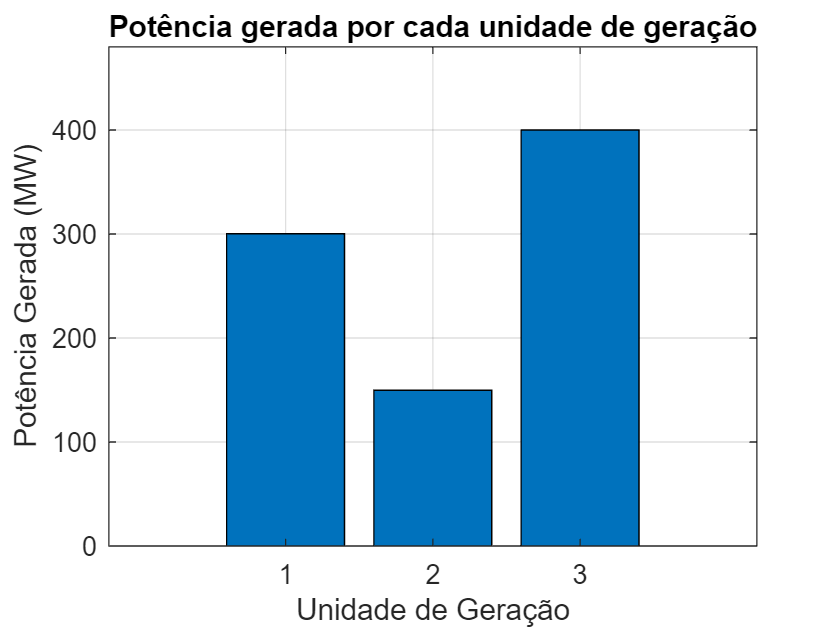


% Gráfico de barras
bar(G, x_best);
xlabel('Unidade de Geração');
ylabel('Potência Gerada (MW)');
title('Potência gerada por cada unidade de geração');
grid on;

ylim([0, max(x_best) * 1.2]);

total_power_generated = sum(x_best);
fprintf('Potência total gerada: %.5f MW\n', total_power_generated);

Potência total gerada: 850.00000 MW


fprintf('Custo da produção ($): %.5f ', best_fitness);

Custo da produção ($): 8234.07920 

disp('Melhor solução encontrada:');

Melhor solução encontrada:


disp(x_best);

   1.0e+02 *

   3.002668069891250   1.497401537590449   3.999930392518301



toc

Elapsed time is 5.652133 seconds.


### Função de custo de produção da unidade de geração termelétrica

function C = unit_cost(PG_k, a_k, b_k, c_k, e_k, f_k, Pmin_G_k)
    C = a_k * PG_k^2 + b_k * PG_k + c_k + abs(e_k * sin(f_k * (Pmin_G_k - PG_k)));
end
